clear all
close all
clc
path = 'InvestmentReplica.mat';
load(path)
Date_ME = XTab.Date(:, :);

Construct a Monster Index to be replicated

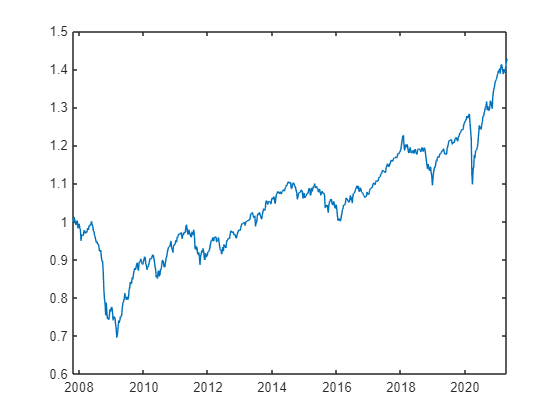

% Synthetic target weights
wHFRXGL = 0.33; 
wMXWO = 0.33;
wLEGATRUU = 0.33;

% Building the target
y = wHFRXGL*price2ret(HFRXGL) + wMXWO*price2ret(MXWO) + wLEGATRUU*price2ret(LEGATRUU); % "Monster Index" returns
target = ret2price(y); % "Monster Index" levels

figure
plot(Date_ME,target)

Set of available future for replication

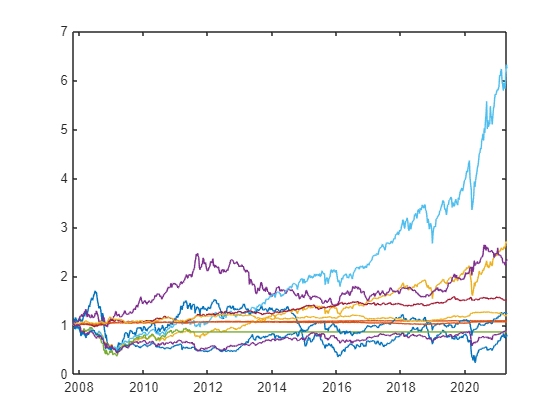

% Futures returns
X = [price2ret(CO1) price2ret(DU1) price2ret(ES1) price2ret(GC1)...
           price2ret(LLL1) price2ret(NQ1) price2ret(RX1) price2ret(TP1)...
           price2ret(TU2) price2ret(TY1) price2ret(VG1)];

figure
plot(Date_ME,ret2price(X))

Define dimensionalities

% Load the return data
portfolioReturns = y;
futuresReturns = X;

n = size(portfolioReturns, 1);  % Number of time steps
m = size(futuresReturns, 2);    % Number of futures

Compute the weekly weights with Kalmann-Filter

% To perfectly replicate portfolio in-sample use:
% V1 = eye(m).*var(futuresReturns); % va cambiato
% V2 = 0; % va cambiato
% P = ones(m,m); 
% x_initial = 0;
% Why? Because it works...

y = portfolioReturns;
% F = eye(m) so it can be omitted
% G = zeros(m) so the associated term is removed
H = futuresReturns;
% D = 0 so the associated term is removed
V1 = eye(m).*std(futuresReturns); 
V2 = std(portfolioReturns); 
% V12 = 0 so the associated term is removed

model = InitializeModel(y, [], [], H, [], V1, V2, []);
x_initial = ones(m,1)*0.065;
y(1)-futuresReturns(1,:)*x_initial

ans = -3.4337e-06

P = ones(m,m)*var(y(1)-futuresReturns(1,:)*x_initial); 
step = 1; % define the rolling windows = one_week*step

[Gain,Weights,yy] = KalmanFilter(model,x_initial,P,step);

Prediction = sum(futuresReturns(2:end,:).*Weights(:,1:end-1)',2);

TE_price = Prediction - y(2:end);
TEV_price = std(TE_price)*sqrt(52);
TE_return = ret2price(Prediction) - target(2:end);
TEV_return = std(TE_return)*sqrt(52);

display(['Case with std: TEV_price=',num2str(TEV_return), ', TEV_return=', num2str(TEV_price)])

Case with std: TEV_price=0.19984, TEV_return=0.031915


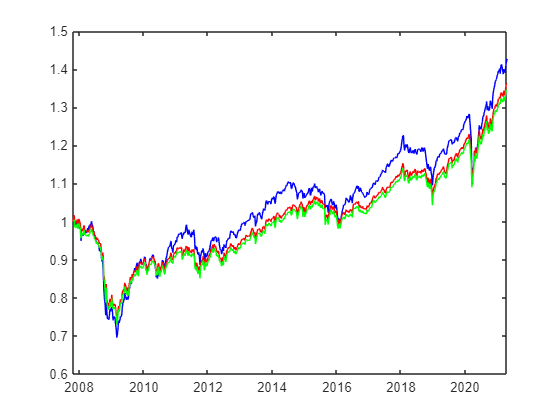

figure()
plot(Date_ME,target,'Color','b')
hold on
plot(Date_ME,ret2price(yy),'Color','r')
plot(Date_ME(2:end),ret2price(Prediction),'g')

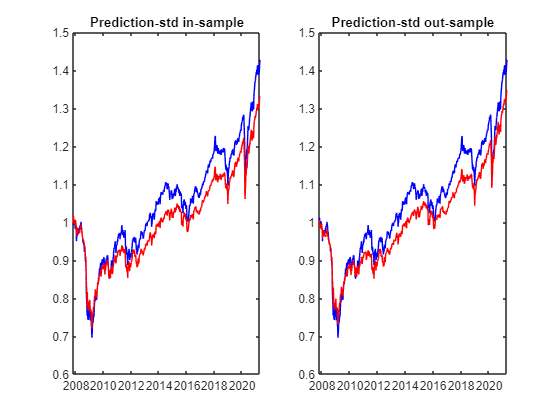

figure()
subplot(1,2,1)
plot(Date_ME,target,'Color','b')
hold on
plot(Date_ME,ret2price(sum(futuresReturns.*Weights',2)),'r')
title('Prediction-std in-sample')

subplot(1,2,2)
plot(Date_ME,target,'Color','b')
hold on
plot(Date_ME(2:end),ret2price(Prediction),'r')
title('Prediction-std out-sample')

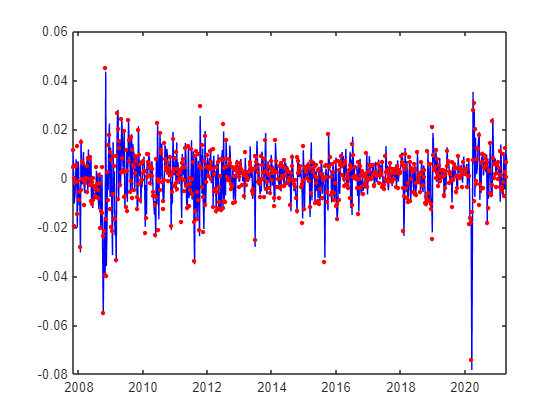

figure()
plot(Date_ME(2:end),y,'Color','b')
hold on
plot(Date_ME(2:end),sum(futuresReturns.*Weights',2),'r.','MarkerSize',10)

Statistical meausers

% Tracking Error = Excess Return = difference between target performance and replica performance.
TE = Prediction - y;

Arrays have incompatible sizes for this operation.

Related documentation

% Tracking Error Volatility = (annualized) standard deviation of Tracking Error.
TEV = std(TE)*sqrt(52)

% Gross Total Return, and Excess Return (ER)
logRClone = diff(log(ret2price(Prediction))); 
logRTarget = diff(log(ret2price(y)));
logTE =  logRClone - logRTarget;
meanTRTarget = exp(mean(logRTarget)*52) - 1
meanTRClone = exp(mean(logRClone)*52) - 1
meanER = exp(mean(logTE)*52) - 1

% Information Ratio (IR)
IR = meanER/TEV

% R-squared
% Compute the residual sum of squares (RSS)
RSS = sum((y - Prediction).^2)

% Compute the total sum of squares (TSS)
TSS = sum((y - mean(y)).^2)

% Calculate R-squared
R_squared = 1 - RSS / TSS

Wheights constant in the month as at it beginning

Weights_monthly = Weights;
for i = 2:n
    if Date_ME(i).Month == Date_ME(i-1).Month
        Weights_monthly(:,i) = Weights(:,i-1);
    else
        Weights_monthly(:,i) = Weights(:,i);
    end
end

Prediction = sum(futuresReturns.*Weights_monthly',2);

figure()
plot(Date_ME(2:end),y,'Color','b')
hold on
plot(Date_ME(2:end),sum(futuresReturns.*Weights_monthly',2),'r.','MarkerSize',10)

% Tracking Error = Excess Return = difference between target performance and replica performance.
TE = Prediction - y;
% Tracking Error Volatility = (annualized) standard deviation of Tracking Error.
TEV = std(TE)*sqrt(52)

Find optimal wheights based on Tev

min_TEV = 9999;
for i = 1:n
    TE = sum(futuresReturns*Weights(:,i),2) - y;
    TEV = std(TE)*sqrt(52);
    if TEV < min_TEV
        min_TEV = TEV;
        Weights_constant = Weights(:,i);
    end
end

Prediction = sum(futuresReturns*Weights_constant,2);

figure()
plot(Date_ME(2:end),y,'Color','b')
hold on
plot(Date_ME(2:end),Prediction,'r.','MarkerSize',10)

figure()
plot(Date_ME,target,'Color','b')
hold on
plot(Date_ME,ret2price(Prediction),'r.','MarkerSize',1)

% Tracking Error = Excess Return = difference between target performance and replica performance.
TE = Prediction - y;
% Tracking Error Volatility = (annualized) standard deviation of Tracking Error.
TEV = std(TE)*sqrt(52)